# Sensitivity Analysis

clc;
clear;
close all;

timeBase = load("SimOutput_2022_12_16_12_21base.mat").out.tout(end);

time.mass = load("SimOutput_2022_12_16_16_43mass.mat").out.tout(end);
time.aero = load("SimOutput_2022_12_16_13_57aero.mat").out.tout(end);
time.roll = load("SimOutput_2022_12_16_15_52roll.mat").out.tout(end);
time.wheelR = load("SimOutput_2022_12_16_17_44wRadius.mat").out.tout(end);
time.P0 = load("SimOutput_2022_12_16_16_24P0mot.mat").out.tout(end);
time.eMot = load("SimOutput_2022_12_16_16_36eMot").out.tout(end);
time.ePV = load("SimOutput_2022_12_16_21_11ePV.mat").out.tout(end);
time.E0bat = load("SimOutput_2022_12_16_21_18E0bat.mat").out.tout(end);
time.UocBat = load("SimOutput_2022_12_17_11_17UocBat.mat").out.tout(end);
time.RiBat = load("SimOutput_2022_12_17_12_03RiBat.mat").out.tout(end);

ylabelNames = {'m_{tot}','c_d , A_f , rho_{a}','c_r','r_w','P_0','e_{mot}','e_{PV}','Q_0','U_{oc}','R_i'};

timeNames = fields(time);
timeLen = length(timeNames);
increaseTime = NaN(timeLen, 1);
for k = 1:timeLen
    increaseTime(k) = time.(timeNames{k}) - timeBase;
end

[increaseTimeSorted, index] = sort(increaseTime);
ylabelNamesSorted = ylabelNames(index);

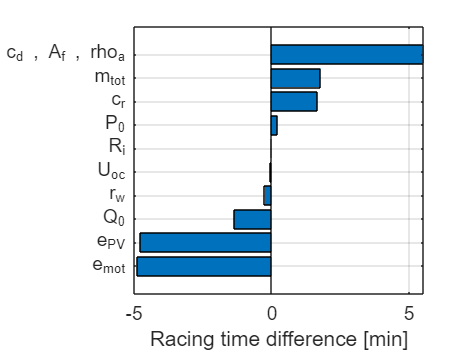

Found the following figure:
  Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [360 278 560 420]
       Units: 'pixels'

  Show all properties



 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.13 or newer to compile the TikZ output.


Error using getGitInfo
Could not find any Git repository in 'C:\Users\giaco\OneDrive - ETH Zurich\BA\IDSCreport_v1.7.0\Template\img' or any of its parents (traversed until 'C:\').

Error in figure2tikz (line 554)
    origFig.UserData = getGitInfo();

Error in latexMatlabPlotSaver (

figure
title('Sensitivity of 1% increase of current parameters')
barh(increaseTimeSorted / 60)
xlabel('Racing time difference [min]')
yticklabels(ylabelNamesSorted)
box on
grid on

figureName = 'sensitivityAnalysis';
saveFolderName = 'C:\Users\giaco\OneDrive - ETH Zurich\BA\IDSCreport_v1.7.0\Template\img';
latexMatlabPlotSaver(figureName, saveFolderName)

saveExcel = false;

if saveExcel
    currentTime = char(string(datetime, "yyyy_MM_dd"));
    dataName = ['SensitivityAnalysisData_', currentTime, '.xlsx'];
    
    writematrix(string(ylabelNamesSorted), dataName)
    writematrix(increaseTimeSorted', dataName,'WriteMode','append')
end % if